#                  Optimization With Second Order Stochastic Dominance

Cleaning Workspace,Command Window and Fomatting numeric type to long. 

clear;
clc;
close all;
format long;

The following two arrays of strings contains list of BSE Companies and their tickers respectively.

Company = {'Infosys','Axis Bank','Asian Paints','Bajaj Auto', 'Bajaj Finance','Bajaj Finserv','Bharti Airtel','HCL', 'HDFC Bank','HDFC', 'Hindustan Unilever','ICICI','IndusInd Bank', 'ITC' ,'Kotak Mahindra Bank', 'L&T','Mahindra & Mahindra','Maruti Suzuki','Nestle','NTPC' ,'ONGC','Power Grid Corporation of India' ,'Reliance Industries' ,'SBI','Sun Pharmaceutical Industries','Tata Steel' ,'TCS', 'Tech Mahindra' ,'Titan','UltraTech Cement'};
tickers = {'INFY.BO','AXISBANK.BO','ASIANPAINT.BO','BAJAJ-AUTO.BO','BAJFINANCE.BO','BAJAJFINSV.BO','BHARTIARTL.BO','HCLTECH.BO','HDFCBANK.BO','HDFC.BO','HINDUNILVR.BO','ICICIBANK.BO','INDUSINDBK.BO','ITC.BO','KOTAKBANK.BO','LT.BO','M&M.BO','MARUTI.BO','NESTLEIND.BO','NTPC.BO','ONGC.BO','POWERGRID.BO','RELIANCE.BO','SBIN.BO','SUNPHARMA.BO','TATASTEEL.BO','TCS.BO','TECHM.BO','TITAN.BO','ULTRACEMCO.BO'};

To download the data from yahoo finance we are using [Yahoo Finance and Quandl data downloader ](https://in.mathworks.com/matlabcentral/fileexchange/68361-yahoo-finance-and-quandl-data-downloader)package.The function getMarketDataViaYahoo() contains the arguments ticker symbol, start date, end date and the frequency by which we want the data.Here we are taking daily prices of stocks.We are downloading the SENSEX values till today's date.

data2 = getMarketDataViaYahoo('^BSESN', '15-Oct-2020', datetime('today'), '1d');
Index = data2(:,"AdjClose");

The 1st column of stock prices stored in all_stock_prices is date and each stock's price in next columns for all the tickers mentioned in the tickers array.

all_stock_prices(:,"Date") = data2(:,"Date");
n = length(tickers);
for i=1:n
   data = getMarketDataViaYahoo(tickers{i}, '15-Oct-2020', datetime('today'), '1d');
  all_stock_prices(:,Company{i}) = data(:,"AdjClose");
end

The price2ret function converts all our stock price and index arrays into their respective return's array. 

Index_ret = price2ret(table2array(Index));
A = table2array(all_stock_prices(:,2:end)); 
all_stock_returns = price2ret(A);

[m,n] = size(all_stock_returns);
u = ones(n,1);
p = 1/m;
v = zeros(m,1);
c = zeros(m,1);
for i=1:m
    for j=1:m
        if Index_ret(i) > v(j)
            v(i) = v(i) + (Index_ret(i) - v(j));
        end
    end
end

We are using Optimisation toolbox to solve our optimisation equations and constraints.

ssd_problem = optimproblem;

 x and d are the optimization variables that are used in the problem.

x = optimvar('x',n,'Lowerbound',0,"UpperBound",1);
d = optimvar('d',m,m,'Lowerbound',0);

Objective function is maximizing expected return.

ssd_problem.ObjectiveSense = 'maximize';  
ssd_problem.Objective = p*sum(all_stock_returns*x);

Constraint 1:

ssd_problem.Constraints.c1 = x'*u ==1 ;

Constraint 2:

const1 = optimconstr(m,m);
for i=1:m
   for j=1:m
      const1(i,j) = d(i,j) >= Index_ret(j) - all_stock_returns(i,:)*x;  
   end
end
ssd_problem.Constraints.c2 = const1;

Constraint 3:

const2 = optimconstr(m,1);
for i=1:m
   const2(i) =  sum(d(:,i))<= v(i)/p;
end
ssd_problem.Constraints.c3 = const2;

This function solves the optimisation problem.

sol = solve(ssd_problem);

Solving problem using linprog.

Optimal solution found.



fprintf("The weights of ssd dominant portfolio with maximum expected return are");

The weights of ssd dominant portfolio with maximum expected return are

T = table(Company',sol.x)

T = 30×2 table
             Var1                     Var2       
    _______________________    __________________

    {'Infosys'            }                     0
    {'Axis Bank'          }                     0
    {'Asian Paints'       }                     0
    {'Bajaj Auto'         }                     0
    {'Bajaj Finance'      }                     0
    {'Bajaj Finserv'      }     0.506424979557671
    {'Bharti Airtel'      }    0.0778907200993277
    {'HCL'                }                     0
    {'HDFC Bank'          }                     0
    {'HDFC'               }                     0
    {'Hindustan Unilever' }                     0
    {'ICICI'              }                     0
    {'IndusInd Bank'      }                     0
    {'ITC'                }                     0
    {'Kotak Mahindra Bank'}     0.104605170360072
    {'L&T'                }    0.0068792634196314


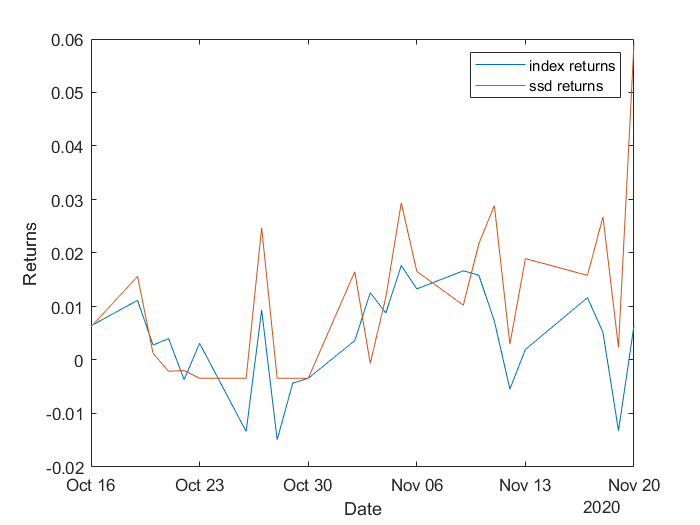

plot(table2array(all_stock_prices(2:end,1)),Index_ret);
hold on;
plot(table2array(all_stock_prices(2:end,1)),all_stock_returns*(sol.x));
legend('index returns','ssd returns');
xlabel('Date'); ylabel('Returns');

portfolio = ["Index","SSD"]';
mean_return = [sum(Index_ret(:))/n,sum(all_stock_returns*(sol.x))/n]';
min_return   = [min(Index_ret(:)),min(all_stock_returns*(sol.x))]';
max_retunrn  = [max(Index_ret(:)),max(all_stock_returns*(sol.x))]';
std_return   = [std(Index_ret(:)),std(all_stock_returns*(sol.x))]';
T = table(portfolio,mean_return,min_return,max_retunrn,std_return)

T = 2×5 table
    portfolio        mean_return            min_return            max_retunrn            std_return     
    _________    ___________________    ___________________    __________________    ___________________

     "Index"     0.00331477858279552    -0.0149084465810621    0.0176688884186014    0.00928019225453991
     "SSD"       0.00957189618307723    -0.0034217407424216    0.0592943478135093       0.01510736786154
